# Import data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 31-Jul-2024 21:35:58

## Set up the Import Options and import the data

% Set import options
opts = spreadsheetImportOptions("NumVariables", 19);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:S64";

% Specify column names and types
opts.VariableNames = ["RowID", "OrderID", "OrderDate", "DateKey", "ContactName", "Country", "City", "Region", "Subregion", "Customer", "CustomerID", "Industry", "Segment", "Product", "License", "Sales", "Quantity", "Discount", "Profit"];
opts.VariableTypes = ["double", "categorical", "categorical", "double", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "double", "categorical", "categorical", "categorical", "string", "double", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, "License", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["OrderID", "OrderDate", "ContactName", "Country", "City", "Region", "Subregion", "Customer", "Industry", "Segment", "Product", "License"], "EmptyFieldRule", "auto");

% Import the data
Book2 = readtable("C:\Users\malig\OneDrive\Desktop\amzonweb\Book2.xlsx", opts, "UseExcel", false);
disp(Book2)

    RowID        OrderID          OrderDate      DateKey         ContactName          Country            City         Region    Subregion           Customer           CustomerID        Industry          Segment               Product                License       Sales     Quantity    Discount    Profit 
    _____    ________________    ___________    __________    _________________    ______________    _____________    ______    _________    ______________________    __________    


% Normalize numerical data to [0, 1]
numericalVars = ["Sales", "Quantity", "Discount", "Profit"];
for i = 1:length(numericalVars)
    var = numericalVars(i);
    Book2.(var) = (Book2.(var) - min(Book2.(var))) / (max(Book2.(var)) - min(Book2.(var)));
end

% Extract the matrix of numerical variables
numericalData = table2array(Book2(:, numericalVars));
categoricalVars = ["OrderID", "OrderDate", "ContactName", "Country", "City", "Region", "Subregion", "Customer", "Industry", "Segment", "Product"];
for i = 1:length(categoricalVars)
    var = categoricalVars(i);
    Book2.(var) = categorical(Book2.(var));
end

% Display the standardized table
disp(Book2);

    RowID        OrderID          OrderDate      DateKey         ContactName          Country            City         Region    Subregion           Customer           CustomerID        Industry          Segment               Product                License         Sales       Quantity    Discount    Profit 
    _____    ________________    ___________    __________    _________________    ______________    _____________    ______    _________    ______________________    __________    <


% Compute the covariance matrix
covMatrix = cov(numericalData);
disp('Covariance Matrix:');

Covariance Matrix:


disp(array2table(covMatrix, 'VariableNames', numericalVars, 'RowNames', numericalVars));

                  Sales       Quantity     Discount       Profit  
                _________    __________    _________    __________

    Sales        0.026992       0.01673     0.007146     -0.011024
    Quantity      0.01673       0.06174    0.0072345    -0.0048803
    Discount     0.007146     0.0072345     0.067787     -0.010236
    Profit      -0.011024    -0.0048803    -0.010236      0.013451





% Compute eigenvalues and eigenvectors
[eigenvectors, eigenvaluesMatrix] = eig(covMatrix);
eigenvalues = diag(eigenvaluesMatrix);

% Sort the eigenvalues and eigenvectors in descending order
[eigenvaluesSorted, index] = sort(eigenvalues, 'descend');
eigenvectorsSorted = eigenvectors(:, index);

% Display the eigenvalues and eigenvectors
disp('Eigenvalues (sorted):');

Eigenvalues (sorted):


disp(eigenvaluesSorted);

    0.0805
    0.0590
    0.0240
    0.0064




disp('Eigenvectors (sorted corresponding to eigenvalues):');

Eigenvectors (sorted corresponding to eigenvalues):


disp(array2table(eigenvectorsSorted, 'VariableNames', numericalVars, 'RowNames', numericalVars));

                 Sales      Quantity     Discount     Profit  
                ________    _________    ________    _________

    Sales       -0.32521     -0.19622    -0.77996      0.49739
    Quantity       -0.61     -0.69355      0.3732    -0.087219
    Discount     -0.6933      0.69234     0.17576     0.095439
    Profit       0.20368    -0.033772     0.47063      0.85784





k = 2;
featureVector = eigenvectorsSorted(:, 1:k);

% Display the feature vector
disp('Feature Vector (top k principal components):');

Feature Vector (top k principal components):


disp(array2table(featureVector, 'VariableNames', strcat('PC', string(1:k)), 'RowNames', numericalVars));

                  PC1          PC2   
                ________    _________

    Sales       -0.32521     -0.19622
    Quantity       -0.61     -0.69355
    Discount     -0.6933      0.69234
    Profit       0.20368    -0.033772




meanData = mean(numericalData);
centeredData = numericalData - meanData;

% Project the centered data onto the principal component axes
projectedData = centeredData * featureVector;

% Display the recast data along the principal components axes
disp('Recast Data Along the Principal Components Axes:');

Recast Data Along the Principal Components Axes:


disp(array2table(projectedData, 'VariableNames', strcat('PC', string(1:k))));

        PC1           PC2   
    ___________    _________

        0.28319     0.027722
        0.17577    -0.091952
        0.30565     0.044073
       -0.45302       0.1201
        0.13106      0.21674
      -0.078453      -0.3917
        0.15342     -0.12876
       -0.25816     -0.18789
       0.055555      0.13024
       0.069183     -0.22287
       -0.57179     -0.49875
       -0.10843    -0.014387
       0.055831      0.13043
       0.027608      0.10326
       -0.63567      0.47513
       -0.46373      0.65068
      -0.067404     -0.34428
        0.30166     0.041417
        0.30584     0.044534
       0.036041      0.11765
      -0.020973     0.043246
      -0.076295     -0.38968
      -0.079507     -0.39246
       0.038858      0.30022
        0.14492     -0.11222
        0.13237      0.21739
         0.2219    -0.047541
        -1.0062     -0.12332
        -0.3019      0.65043
       0.045412      0.12334
   

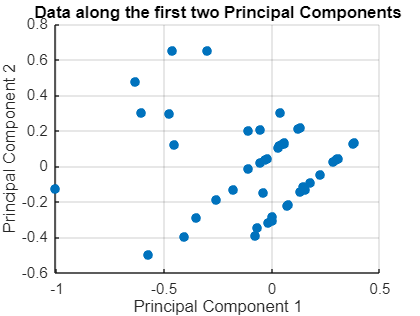


figure;
scatter(projectedData(:,1), projectedData(:,2), 'filled');
title('Data along the first two Principal Components');
xlabel('Principal Component 1');
ylabel('Principal Component 2');
grid on;

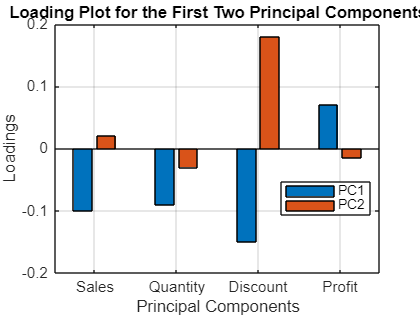


% Example data for loadings of the first two principal components
loadings = [
    -0.1, 0.02;   % Sales
    -0.09, -0.03; % Quantity
    -0.15, 0.18;  % Discount
    0.07, -0.015; % Profit
];

% Create a bar plot of the loadings
figure;
bar(loadings);

% Set the x-axis labels to the variable names
set(gca, 'XTickLabel', {'Sales', 'Quantity', 'Discount', 'Profit'});

% Add title and labels
title('Loading Plot for the First Two Principal Components');
xlabel('Principal Components');
ylabel('Loadings');

% Add a legend for the principal components
legend('PC1', 'PC2', 'Location', 'best');
% Add grid lines for better readability
grid on;
% Adjust y-axis limits to match the range in your provided image
ylim([-0.2 0.2]);